# How To Create an OFDM Signal

## Introduction

 OFDM - Orthogonal Frequency Division Multiplexing is a modulation method widely used in today's wireless wideband digital communications. Among its uses are: Bluetooth, LTE, WLAN, DSL interenet access, ect. In this small piece we will go over the steps to create an OFDM signal using MATLAB, and compare it to MATLAB's built-in functions.

The overall path of the signal can be described in the figure below:

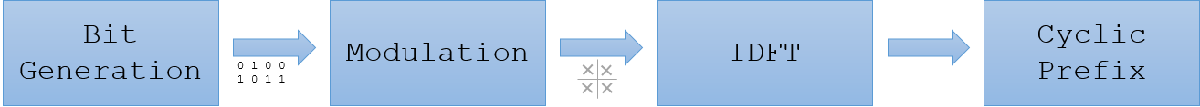

## Creating a bit stream

The first thing we'll do is create the bits we would like to transfer:

NumOfBits = 500;
sig = randi([0 1], 1, NumOfBits); %create 500 bits

Next we'll want to modulate the signal to create our symbols. To do so, we would need to set up some parameters, and play a bit with our signal:

    * Bit period:

Tb = 1e-3; %bit period (seconds)

    * Sampling Rate

Fs = 100/Tb; % our sample rate (Hz)

    * Carrier Frequency (Baseband)

fc = 5e3;

    * Create time domain of the signal:

sig_t = repelem(sig, 100); %now each signal is sampled 100 times.
t = 0:(1/Fs):((length(sig_t)-1)/Fs); %0 - time zero; 1/Fs - our time step

Now let's view our signal in the time domain:

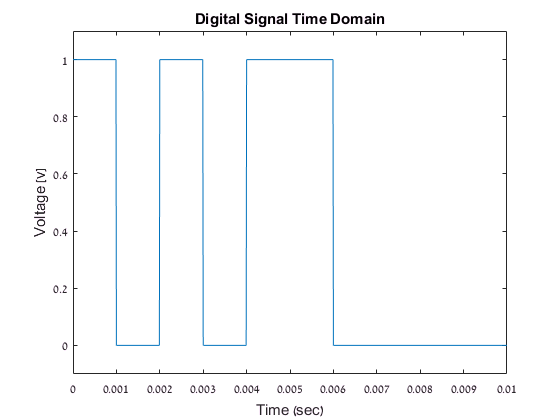

figure(1);
plot(t, sig_t); title('Digital Signal Time Domain');
xlabel('Time (sec)'); ylabel('Voltage [v]'); xlim([0 10*Tb]); ylim([-0.1 1.1]);

## Modulating the Signal

We'll use a decide on the modulation method we'd like to use. Below are a few modulation methods: BPSK, QPSK, 16-QAM:

t_sym = 1/Fs:1/Fs:Tb;
ModulationMethod = '16-QAM';
sym_t = zeros(1, NumOfBits*(Fs*Tb));


switch ModulationMethod
    case 'BPSK'
        % preallocate:
        sym = zeros(1,NumOfBits);
        % run loop
        for idx =1:NumOfBits
            if sig(idx)==1       %0
                sym_t((1:Fs*Tb) + (idx-1)*Fs*Tb)=  cos(2*pi*t_sym*fc+pi);
                sym(idx) = 1;
            else                 %1
                sym_t((1:Fs*Tb) + (idx-1)*Fs*Tb)=  cos(2*pi*t_sym*fc+0);
                sym(idx) = 0
            end
        end
    case 'QPSK' %Done!
        if mod(NumOfBits,2) ~=0 % add a zero at the end if not divisible by 2.
            NumOfBits = NumOfBits +1;
            sig(NumOfBits) = 0;
        end
        sym = zeros(1,NumOfBits/2);

        for idx =1:2:NumOfBits
            switch num2str(sig(idx:(idx+1)))
                case '0  0'
                    sym_t((1:2*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+pi/4));
                    sym((idx+1)/2) = exp(1i*(pi/4));
                case '1  0'
                    sym_t((1:2*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-pi/4));
                    sym((idx+1)/2) = exp(1i*(-pi/4));
                case '0  1'
                    sym_t((1:2*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+3*pi/4));
                    sym((idx+1)/2) = exp(1i*(3*pi/4));
                case '1  1'   
                    sym_t((1:2*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-3*pi/4));
                    sym((idx+1)/2) = exp(1i*(-3*pi/4));
            end
        end
    case '16-PSK' 
        if mod(NumOfBits,4) ~=0 % add a zeros at the end if not divisible by 4.
            sig(end:(end+mod(NumOfBits,4))) = 0;
            NumOfBits = NumOfBits +mod(NumOfBits,4);   
        end
        sym = zeros(1,NumOfBits/4);
        for idx = 1:4:NumOfBits
            switch num2str(sig(idx:(idx+3)))
                case '0  0  0  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+pi/16));
                    sym((idx+3)/4) = exp(1i*(pi/16));
                case '0  0  0  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+3*pi/16));
                    sym((idx+3)/4) = exp(1i*(3*pi/16));
                case '0  0  1  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+5*pi/16));
                    sym((idx+3)/4) = exp(1i*(5*pi/16)); 
                case '0  0  1  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+7*pi/16));
                    sym((idx+3)/4) = exp(1i*(7*pi/16));
                case '0  1  0  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+9*pi/16));
                    sym((idx+3)/4) = exp(1i*(9*pi/16));
                case '0  1  0  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+11*pi/16));
                    sym((idx+3)/4) = exp(1i*(11*pi/16)); 
                case '0  1  1  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+13*pi/16));
                    sym((idx+3)/4) = exp(1i*(13*pi/16));
                case '0  1  1  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc+15*pi/16));
                    sym((idx+3)/4) = exp(1i*(15*pi/16));
                case '1  0  0  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-pi/16));
                    sym((idx+3)/4) = exp(1i*(-pi/16));
                case '1  0  0  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-3*pi/16));
                    sym((idx+3)/4) = exp(1i*(-3*pi/16));
                case '1  0  1  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-5*pi/16));
                    sym((idx+3)/4) = exp(1i*(-5*pi/16));
                case '1  0  1  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-7*pi/16));
                    sym((idx+3)/4) = exp(1i*(-7*pi/16));
                case '1  1  0  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-9*pi/16));
                    sym((idx+3)/4) = exp(1i*(-9*pi/16));
                case '1  1  0  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-11*pi/16));
                    sym((idx+3)/4) = exp(1i*(-11*pi/16));
                case '1  1  1  0'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-13*pi/16));
                    sym((idx+3)/4) = exp(1i*(-13*pi/16));
                case '1  1  1  1'
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  exp(1i*(2*pi*t_sym*fc-15*pi/16));
                    sym((idx+3)/4) = exp(1i*(-15*pi/16));
            end
        end
    case '16-QAM' 
        t_sym = 1/Fs:1/Fs:4*Tb;
        sym_t = zeros(1, NumOfBits*(Fs*Tb));
        if mod(NumOfBits,4) ~=0 % add a zeros at the end if not divisible by 4.
            sig(end:(end+mod(NumOfBits,4))) = 0;
            NumOfBits = NumOfBits +mod(NumOfBits,4);   
        end
        sym = zeros(1,NumOfBits/4);
        for idx = 1:4:NumOfBits
            % 3*sqrt(2) = far out bits (full pi/4)
            % sqrt(2) = small bits (0.25)
            % sqrt(10) = medium
            small_phase = angle(1i+3); % relevent for: 1001, 0001v, 0011v, 1011v
            switch num2str(sig(idx:(idx+3)))
                case '0  0  0  0'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)= 3*sqrt(2)*exp(1i*(2*pi*t_sym*fc+3*pi/4));       
                    sym((idx+3)/4) = 3*sqrt(2)*exp(1i*(3*pi/4));
                case '0  0  0  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)= sqrt(10)*exp(1i*(2*pi*t_sym*fc+pi-small_phase));         
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(pi-small_phase));
                case '0  0  1  0'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  3*sqrt(2)*exp(1i*(2*pi*t_sym*fc-3*pi/4));    
                    sym((idx+3)/4) = 3*sqrt(2)*exp(1i*(-3*pi/4)); 
                case '0  0  1  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(10)*exp(1i*(2*pi*t_sym*fc+pi+small_phase));
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(pi +small_phase));
                case '0  1  0  0'         %VV 
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(10)*exp(1i*(2*pi*t_sym*fc+pi/2+small_phase)); 
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(pi/2+small_phase));
                case '0  1  0  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(2)*exp(1i*(2*pi*t_sym*fc+3*pi/4)); 
                    sym((idx+3)/4) = sqrt(2)*exp(1i*(3*pi/4)); 
                case '0  1  1  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(2)*exp(1i*(2*pi*t_sym*fc-3*pi/4)); 
                    sym((idx+3)/4) = sqrt(2)*exp(1i*(-3*pi/4));
                case '0  1  1  0'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(10)*exp(1i*(2*pi*t_sym*fc-pi/2-small_phase));
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(-pi/2-small_phase));
                case '1  0  0  0'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  3*sqrt(2)*exp(1i*(2*pi*t_sym*fc+pi/4));
                    sym((idx+3)/4) = 3*sqrt(2)*exp(1i*(pi/4));
                case '1  0  0  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(10)*exp(1i*(2*pi*t_sym*fc+small_phase)); 
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(small_phase));
                case '1  0  1  0'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  3*sqrt(2)*exp(1i*(2*pi*t_sym*fc-pi/4)); 
                    sym((idx+3)/4) = 3*sqrt(2)*exp(1i*(-pi/4));
                case '1  0  1  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(10)*exp(1i*(2*pi*t_sym*fc-small_phase));
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(-small_phase));
                case '1  1  0  0'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(10)*exp(1i*(2*pi*t_sym*fc+pi/2-small_phase)); 
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(pi/2-small_phase));
                case '1  1  0  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(2)*exp(1i*(2*pi*t_sym*fc+pi/4));
                    sym((idx+3)/4) = sqrt(2)*exp(1i*(pi/4));
                case '1  1  1  0'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(10)*exp(1i*(2*pi*t_sym*fc-pi/2+small_phase));
                    sym((idx+3)/4) = sqrt(10)*exp(1i*(-pi/2+small_phase));
                case '1  1  1  1'         %VV
                    sym_t((1:4*Fs*Tb) + (idx-1)*Fs*Tb)=  sqrt(2)*exp(1i*(2*pi*t_sym*fc-pi/4)); 
                    sym((idx+3)/4) = sqrt(2)*exp(1i*(-pi/4));
            end
        end
    otherwise
        error('Can only select BPSK, QPSK, 16-PSK, or 16-QAM');
end

Now let's view our signal in the time domain:

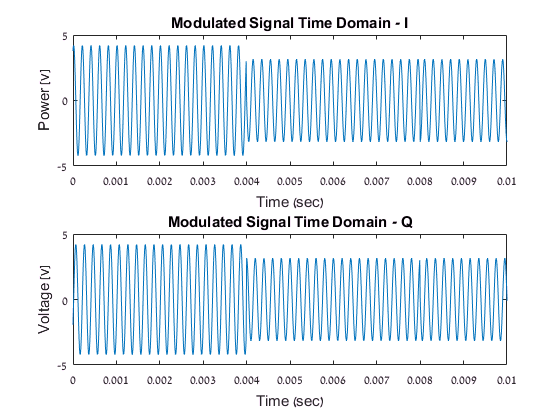

figure(2);
subplot(2,1,1);
plot(t, real(sym_t)); title('Modulated Signal Time Domain - I');
xlabel('Time (sec)'); ylabel('Power [v]'); xlim([0 10*Tb]); 
subplot(2,1,2);
plot(t, imag(sym_t)); title('Modulated Signal Time Domain - Q');
xlabel('Time (sec)'); ylabel('Voltage [v]'); xlim([0 10*Tb]); 

## Serial to Parallel Conversion

The data symbol stream is divided into blocks. Each block will later be mapped to an OFDM symbol. Inside the frame each symbol will be modulated to a subcarrier.  $N_c$  will denote the number of diffrent carriers. 

Nc = 10;
if mod(length(sym), 10) ~=0
    sym(end:(end+mod(length(sym),10))) = sym(end); %we reapeat the last symbol if we don't have enough bits.
end
sym_paral = reshape(sym, 10, []);

Now each 

## IDFT Modulation

After we finish with the cyclic prefix we'd like to create the  OFDM signal. First, a few words on OFDM modulation:

OFDM is a form of multicarrier modulation. The use of OFDM means the carriers are orthogonal to each other thus a carrier is allowed to overlap with its neighbor in the frequency domain.

For our system $T_s =1\mathrm{ms}$ which means the discrete spectrum is between: $\pm \frac{N_c \mp 0\ldotp 5}{2T_s }$ that corresponds to $f_c +\left\lbrack \frac{9\ldotp 5}{2∗{10}^{-3} }\text{ }\text{ }-\frac{10\ldotp 5}{2∗{10}^{-3} }\right\rbrack =f_c +\left\lbrack 4750\text{  }-5250\right\rbrack \text{ }\mathrm{Hz}$

The idea is to 

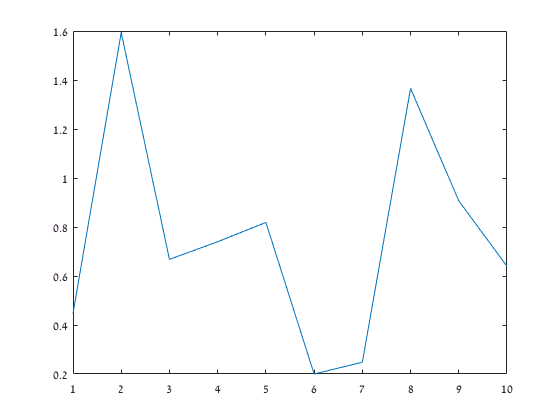

ofdm_sym = ifft(sym_paral, Nc); 
figure(4);
plot(abs(ofdm_sym(:,3)));

Thus, we have an OFDM signal with 10 subcarriers.

## Cyclic Prefix

Cyclic Prefixes are used in OFDM in order to combat multipath by making channel estimation easy[1]. By using cyclic prefix we resolve the problem of transmitting finite duration sinsuids and transform them back to eigenfunctions.. This is done by taking the block of symbols with length $N_c$ and adding $L-1$ symbols at the end of each frame.


$$\begin{array}{l}
d=\left\lbrack d\left\lbrack 0\right\rbrack ;d\left\lbrack 1\right\rbrack ;\ldotp \ldotp \ldotp d\left\lbrack N_c -1\right\rbrack \right\rbrack \to x=\left\lbrack d\left\lbrack N_c -L-1\right\rbrack ;d\left\lbrack N_c -L-2\right\rbrack ;\ldotp \ldotp \ldotp d\left\lbrack N_c -1\right\rbrack ;d\left\lbrack 0\right\rbrack ;\ldotp \ldotp \ldotp d\left\lbrack N_c -1\right\rbrack \right\rbrack \\
d=\left\lbrack d\left\lbrack 0\right\rbrack ;d\left\lbrack 1\right\rbrack ;\ldotp \ldotp \ldotp d\left\lbrack 9\right\rbrack \right\rbrack \to x=\left\lbrack d\left\lbrack 4\right\rbrack ;d\left\lbrack 5\right\rbrack ;d\left\lbrack 6\right\rbrack ;\ldotp \ldotp \ldotp d\left\lbrack 9\right\rbrack ;d\left\lbrack 0\right\rbrack ;d\left\lbrack 1\right\rbrack ;\ldotp \ldotp \ldotp \ldotp d\left\lbrack 9\right\rbrack \right\rbrack 
\end{array}$$


To do so, we first have to re-arrange the block into frames. We'll chose $N_c =10$ and $L=7$  so the IDFT length will be 16.

The arrangment will look like this:

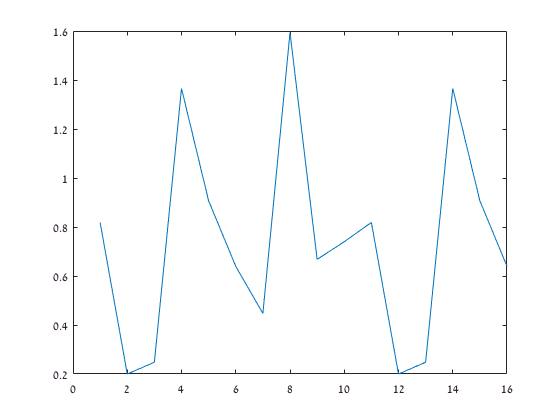

L = 7;
ofdm_sym_cp       = [ofdm_sym((end-L+2):end ,:); ofdm_sym]; %plus 2 instead of 1 because of indexing 0 vs 1
figure(5);
plot(abs(ofdm_sym_cp(:,3)));

Now we have a NumOfBits/10 X 17 matrix that corresponds to the symbols we're going to send.

## Guard Bands

Guard bands are the unused part of the frequency spectrum used to prevent interference. 

## Bibliography

[1] David Tse, Fundamentals of Wireless Communication, Cambridge University Press, 2005, page 96.

## End of demo

This demo was written by Ronen Cohen

You can contact him via email: ronenfm@gmail.com